% 打开 PCM 格式的音频文件
fid = fopen('data/20240103201840(1).pcm', 'r');

% 读取 PCM 文件中的音频数据
audio_data = fread(fid, 'int16'); % 根据实际数据类型选择适当的格式，这里假设数据是 int16 格式
fclose(fid);

% 获取采样率等信息，这些信息可能需要提前了解
% 例如，如果采样率是 44100 Hz，可以手动设置采样率
fs = 48000;

% 在此之后可以进行必要的信号预处理步骤，例如消除噪声、滤波或归一化等

% 设定 FFT 的参数
fft_length = 2048; % FFT 窗口的长度
time_slots = floor(length(audio_data) / fft_length); 

% 初始化存储梯度特征的矩阵为一个空矩阵
gradient_matrix = zeros(time_slots, fft_length);

% 初始化存储梯度特征的矩阵为一个空矩阵
gradient_matrix = zeros(time_slots - 1, fft_length); % 减去1，因为会计算连续时间段的差异

% 计算频域信号和梯度
for t = 2:time_slots % 从第2个时间段开始
    start_index_t = (t - 1) * fft_length + 1;
    end_index_t = t * fft_length;
    prev_start_index_t = (t - 2) * fft_length + 1;

    if end_index_t <= length(audio_data) && prev_start_index_t >= 1
        % 计算当前时间段和前一个时间段的频域信号
        signal_fft_t = fft(audio_data(start_index_t : end_index_t), fft_length);
        prev_signal_fft_t = fft(audio_data(prev_start_index_t : prev_start_index_t + fft_length - 1), fft_length);

        % 计算梯度，考虑到了环境噪声和唇部运动引起的信号差异
        gradient_matrix(t - 1, :) = abs(signal_fft_t - prev_signal_fft_t);
    end
end

file_path = 'gradient_matrix_data.txt';

% 使用 dlmwrite 函数将矩阵保存为文本文件，用空格分隔数据
dlmwrite(file_path, gradient_matrix, ' ');
disp(gradient_matrix);

   1.0e+06 *

  列 1 至 17

    0.0359    0.0495    0.0960    0.1225    0.0139    0.0545    0.0107    0.0178    0.0157    0.0100    0.0208    0.0142    0.0133    0.0228    0.0078    0.0239    0.0152
    0.0005    0.1138    0.0471    0.2309    0.0047    0.0902    0.0171    0.0433    0.0177    0.0139    0.0306    0.0258    0.0375    0.0036    0.0205    0.0201    0.0207
    0.0111    0.1554    0.1662    0.1342    0.1258    0.0721    0.0376    0.0413    0.0165    0.0075    0.0135    0.0140    0.0189    0.0094    0.0181    0.0162    0.0061
    0.0305    0.1722    0.2143    0.1143    0.0790    0.0415    0.0228    0.0252    0.0073    0.0092    0.0109    0.0091    0.0082    0.0021    0.0124    0.0126    0.0041
    0.0032    0.0023    0.0015    0.0010    0.0004    0.0002    0.0003    0.0004    0.0002    0.0003    0.0004    0.0001    0.0001    0.0002    0.0001    0.0002    0.0002
    0.0013    0.0009    0.0002    0.0002    0.0002    0.0001    0.0001    0.0000    0.0001    0.0000    0.0001    0.000


disp('矩阵已保存为 gradient_matrix_data.txt 文件');

矩阵已保存为 gradient_matrix_data.txt 文件


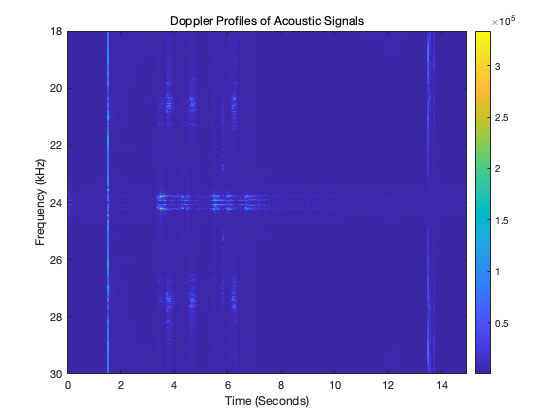

% 计算每个时间段的持续时间（秒）
time_per_slot = fft_length / fs;

% 生成时间轴（秒）
time_axis = (0:size(gradient_matrix, 1) - 1) * time_per_slot;

% 计算每个频率 bin 的宽度（Hz）
bin_width_hz = fs / fft_length;

% 将频率轴转换为 kHz 单位
frequency_axis_khz = (0:size(gradient_matrix, 2) - 1) * bin_width_hz / 1000; % 转换为 kHz

% 找到最接近频率轴上的值对应的索引
[~, index_min] = min(abs(frequency_axis_khz - 18)); % 15 kHz
[~, index_max] = min(abs(frequency_axis_khz - 30)); % 35 kHz

% 裁剪图像，只保留感兴趣的频率范围
cropped_image = gradient_matrix(:, index_min:index_max);

% 更新频率轴
cropped_frequency_axis = frequency_axis_khz(index_min:index_max);

% 绘制裁剪后的热图
figure;
imagesc(time_axis, cropped_frequency_axis, cropped_image');
title('Doppler Profiles of Acoustic Signals');
xlabel('Time (Seconds)');
ylabel('Frequency (kHz)');
colorbar; % 显示颜色条